# Blatt 01, Aufgabe 03

## (a)

Erstellen Sie ein Programm `randomCircle(n)`, welches $n$ zufaellig erstellte Punkte $x_i \in (-1,1)^2$, $i = 1,\ldots,n$, plottet, wobei jede Zahl $x_i$ mit $\|x_i\|_2 \leq 1$als roter Punkt dargestellt werden soll und jede Zahl $x_i$ mit $\|x_i\|_2 > 1$ als blaues Quadrat.

**HInweis: **Sie duerfen die Befehle `rand(n,m)` zum Erstellen der Zufallszahlen und `norm(x,p)` zur Berechnung der Norm verwenden.

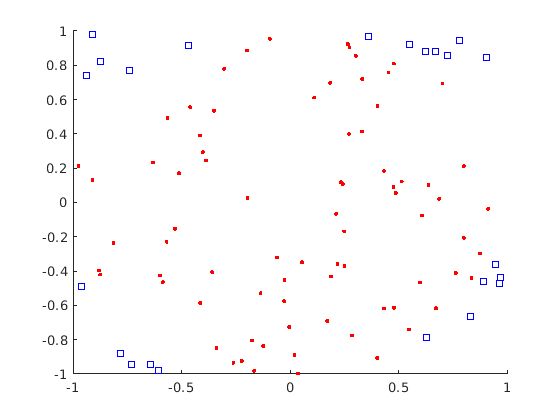

figure
n = 100;
randomCircle(n)

Extra Aufgabe (ohne Punkte): Versuchen Sie die Geschwindigkeit des Programmes `randomCircle` noch zu verbessern.

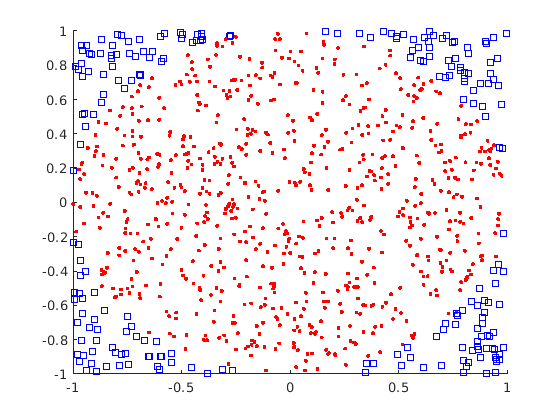

figure
n = 1000;

tic 
randomCircle(n)

toc % zeigt die Zeit an die seit tic vergangen ist

Elapsed time is 0.573333 seconds.


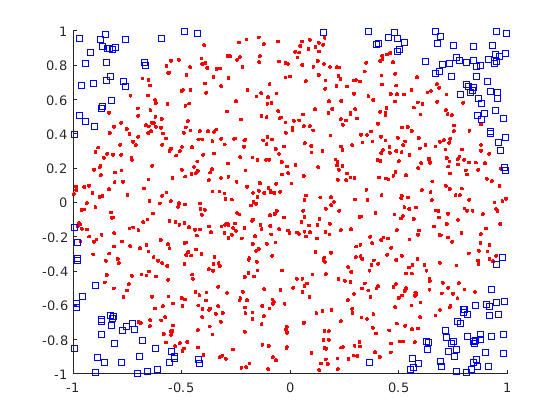

figure
tic
fastRandomCircle(n)

toc

Elapsed time is 0.019520 seconds.


## (b)

Plotten Sie die Funktionen $f_1(\theta) = \sin(\theta)$, $f_2(\theta) = \cos(\theta)$ und $f_3(\theta) = \sin(\theta) \cos(\theta)$ im Intervall $[-\pi,\pi]$. Verwenden Sie unterschiedliche Farben und Linientypen fuer die Darstellung dieser Funktionen. Erstellen Sie eine sinnvolle Achsenbeschriftung und eine Legende fuer das resultierende Bild.

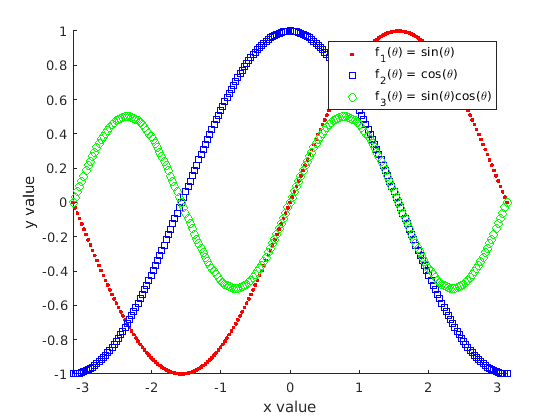

figure

%% Loesung Aufgabe (b): %%
theta = -pi:pi/100:pi;
f1 = sin(theta);
f2 = cos(theta);
f3 = f1.*f2;
hold on
plot(theta,f1,'r.')
plot(theta,f2,'bs')
plot(theta,f3,'go')
xlim([-pi, pi])
xlabel('x value')
ylabel('y value')
legend(texlabel('f_1(theta) = sin(theta)'),texlabel('f_2(theta) = cos(theta)'),texlabel('f_3(theta) = sin(theta)cos(theta)'))



%% %%

# Separat definierte Funktionen:

## (a)

Definition von `randomCircle`:

function randomCircle(n)
% Plottet n Zufalls-Koordinaten in (-1,1)^2 und stellt diese als roten
% Kreis dar, falls diese im Einheitskreis liegen und als blaues 
% Quadrat sonst

punkte = 2*rand(n,2) -1;

hold on

for i = 1:n
    if norm(punkte(i,:),2) > 1
        plot(punkte(i,1), punkte(i,2), 'bs');
    else
        plot(punkte(i,1), punkte(i,2), 'r.');
    end
end

hold off
end

An dieser Stelle eine Warnung: Nach laengerer Benutzung von MATLAB koennen manchmal ungewoehnliche Programmierstile auftreten.

function fastRandomCircle(n)

punkte = 2*rand(n,2) -1;

distance = punkte(:,1).^2 + punkte(:,2).^2;

inCircle = find(distance <= 1);
outCircle = find(distance >1);

hold on 

plot(punkte(inCircle,1), punkte(inCircle,2), 'r.');

plot(punkte(outCircle,1), punkte(outCircle,2), 'bs');

hold off
end